# Discrete Fourier Transform vs MATLAB FFT

Initialize grid and degree information

% half number sample points
m = 11;      

% degree of approximation (n <= m or risk of aliasing)
n = m;       

% build 2m equally spaced grid points over [-pi, pi]
x = linspace(-pi, pi, 2*m + 1); 
x(end) = [];
% fine grid for evaluating functions and their approximations
xFine = linspace(-pi, pi, 1e5);
xFine(end) = [];

Choose the function to approximate

% sample the function at 2m points, then again on the fine grid

% x.^p
% p = 5;
% fSample = x.^p;
% fFine = xFine.^p;

% square wave / sign function (?)
fSample = double(x < 0)*(-1) + double(x >= 0)*1;
fFine = double(xFine < 0)*(-1) + double(xFine >= 0)*1;

% runge function
% fSample = 1 ./ (1 + 25*x.^2);
% fFine = 1 ./ (1 + 25*xFine.^2);

% sawtooth wave 
% fSample = mod(x + pi, 2*pi) - pi;
% fFine = mod(xFine + pi, 2*pi) - pi;

% abs value
% fSample = abs(x);
% fFine = abs(xFine);

% high frequency sine wave
% fSample = sin(8*x);
% fFine = sin(8*xFine);



Compute the discrete Fourier coefficients $a_k$ and $b_k$, given by

$a_k =\frac{1}{m}\sum_{j=0}^{2m-1} y_j \;\cos \left(k\;x_j \right)$,    for each k = 0, 1, ..., n

and

$b_k =\frac{1}{m}\sum_{j=0}^{2m-1} y_j \;\sin \left(k\;x_j \right)$,    for each k = 0, 1, ..., n - 1

% initialize coefficient vectors
ak = zeros(n, 1);
bk = ak;

% explicitly compute a0 
a0 = mean(fSample);

% assign ak, the cosine coefficients
for k = 1:n
    sum = 0;
    for j = 1:2*m
        sum = sum + fSample(j).*cos(k * x(j));
    end
    ak(k) = sum/m;
end

% assign bk, the sine coefficients
for k = 1:n-1
    sum = 0;
    for j = 1:2*m
        sum = sum + fSample(j).*sin(k * x(j));
    end
    bk(k) = sum/m;
end

Build the discrete Fourier series approximaiton of degree n on the fine grid

% initialize approximation
polyApprox = (a0) * ones(size(xFine));

% add the coefficients for the 1 <= k <= n-1 terms
for k = 1:n-1
    polyApprox = polyApprox + ak(k)*cos(k*xFine) + bk(k)*sin(k*xFine);
end

% add half the k = n cosine term 
polyApprox = polyApprox + 0.5*(ak(n)*cos(n*xFine));

Now, approximate the same function using MATLABs built in FFT function

% build complex fourier coefficients through built in FFT
fhat = fft(fSample)/(2*m);

% shift domain from [0, 2pi] to [-pi, pi]
k = 0:2*m-1;
fhat = fhat .* exp(1i * k * pi);

% extract fourier coefficients
a0_fft = real(fhat(1));
ak_fft = 2*real(fhat(2:n));
bk_fft = -2*imag(fhat(2:n));
an_fft = real(fhat(m+1));

Build the FFT approximation of degree n on the fine grid

% initialize approximation
polyApprox_fft = a0_fft * ones(size(xFine));

% add the coefficients for the 1 <= k <= n-1 terms
for k = 1:n-1
    polyApprox_fft = polyApprox_fft + ak_fft(k)*cos(k*xFine) + bk_fft(k)*sin(k*xFine);
end

% add half the k = n cosine term
polyApprox_fft = polyApprox_fft + an_fft * cos(n * xFine);

Plots:

Discrete Fourier Transform Approximation (manual only)

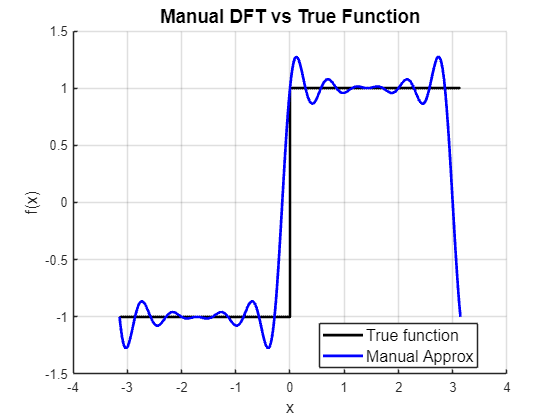

figure
hold on
plot(xFine, fFine, 'k', 'LineWidth', 2, 'DisplayName', 'True function')       
plot(xFine, polyApprox, 'b', 'LineWidth', 2, 'DisplayName', 'Manual Approx') 

title('Manual DFT vs True Function', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)

legend('Location', 'best', 'FontSize', 12, 'Box', 'on')

grid on

Discrete Fourier Transform Approximation with sampled function values (manual only)

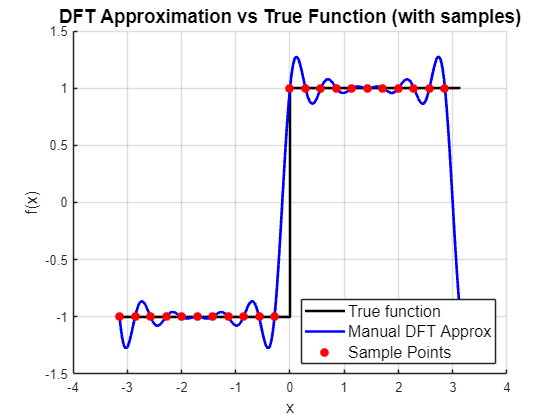

figure
hold on

plot(xFine, fFine, 'k', 'LineWidth', 2, 'DisplayName', 'True function')
plot(xFine, polyApprox, 'b', 'LineWidth', 2, 'DisplayName', 'Manual DFT Approx')
plot(x, fSample, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r', 'DisplayName', 'Sample Points')
title('DFT Approximation vs True Function (with samples)', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)

legend('Location', 'best', 'FontSize', 12, 'Box', 'on')

grid on

Plot Comparison of manual DFT and MATLABs FFT

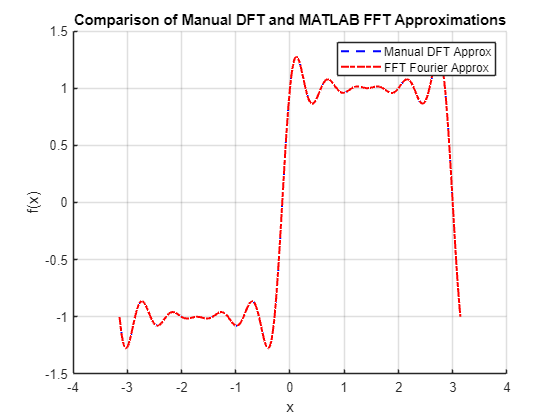

figure
hold on
plot(xFine, polyApprox, 'b--', 'LineWidth', 1.5)    
plot(xFine, polyApprox_fft, 'r-.', 'LineWidth', 1.5)
legend('Manual DFT Approx', 'FFT Fourier Approx')
title('Comparison of Manual DFT and MATLAB FFT Approximations')
xlabel('x')
ylabel('f(x)')
grid on
hold off

Error between manual DFT and MATLABS FFT (infinity norm)

max_diff1 = max(abs(polyApprox - polyApprox_fft));
disp(max_diff1)

   2.2204e-15



Error between manual DFT and actual function (infinity norm)

max_diff2 = max(abs(polyApprox - fFine));
disp(max_diff2)

    1.9998

